# **JacobiNS**

[Jacobi elliptic function ns](https://dlmf.nist.gov/22)

## Definition


$$\mathrm{ns}\left(x\left|m\right.\right)\equiv \frac{1}{\mathrm{sn}\left(x\left|m\right.\right)}$$



$$\mathrm{ns}\left(x,k\right)\equiv \mathrm{ns}\left(x\left|k^2 \right.\right)$$


where *m *is the parameter, *k *is the modulus, and  sn is Jacobi elliptic functions function.

Domain: $-\infty <x<\infty$, $-\infty <m<\infty$. For the specified domain, the  codomain of ns is the set of real numbers.

Basic features:

$\mathrm{ns}\left(x+4K\left(m\right)\left|m\right.\right)=\mathrm{ns}\left(x\left|m\right.\right)$  (periodic) ,  $\mathrm{ns}\left(-x\left|m\right.\right)=-\mathrm{ns}\left(x\left|m\right.\right)$ (odd)

Special values:


$$\mathrm{ns}\left(0\left|m\right.\right)=\infty$$


$\mathrm{ns}\left(x\left|0\right.\right)=1/\mathrm{sin}\;x$,  $\mathrm{ns}\left(x\left|1\right.\right)=\coth \;x$

Identities:


$$\mathrm{ns}\left(x\left|m\right.\right)=\sqrt{m}\mathrm{ns}\left(x\sqrt{m}\left|m^{-1} \right.\right)$$


## Syntax

Y = JacobiNS(X,K)

y = jns(x,k)

Y = mJacobiNS(X,M)

y = mjns(x,m)

## Densription

Y = JacobiNS(X,K) returns the Jacobi elliptic function $\mathrm{ns}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be nsalar. **JacobiNS** is the wrapper function which calls the functions **jns** element-wise via the function **ufun2**.

y = jns(x,k) returns the Jacobi elliptic function $\mathrm{ns}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real nsalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed. **jns** calls the functions **sncndn **for calculation of$\;\mathrm{ns}\left(x,k\right)$ .

Y = mJacobiNS(X,M) returns the Jacobi elliptic function $\mathrm{ns}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be nsalar. **mJacobiNS** is the wrapper function which calls the function **mjns** element-wise via the function **ufun2**.

y = mjns(x,m) returns the Jacobi elliptic function $\mathrm{ns}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real nsalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed.  **mjns** calls the functions **sncndn **for calculation of $\mathrm{ns}\left(x\left|m\right.\right)$ .

**sncndn **implements the AGM transformation for simultaneously  computation of the functions *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

## **Numerical Examples**

**Salar input**

format long
k = 0.5; 
x = 0.5;
[jns(x,k), JacobiNS(x,k), mjns(x,k^2), mJacobiNS(x,k^2)]

ans =    2.104895638558431   2.104895638558431   2.104895638558431   2.104895638558431


Accuracy

fprintf('%.16g\n',jns(3,5))

6.569900420777404


% Maple 6.56990042077741292

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobins.html)

disp(mJacobiNS([2 1 -3],[1 2 3]))

   1.037314720727548   1.487869613352855   1.732068902070096



fprintf('%.16g\n',mjns(3,5))

32.10811118995555


% MATLAB 32.10811118995561_1054545195854805


Identities

x=2;
m = 0.12; % m > 0
disp(mjns(x,m)-sqrt(m)*mjns(x*sqrt(m),1/m))

     0



**Vector input**

X=[1 2 3 4];
disp(JacobiNS(X,0)-1./sin(X))

     0     0     0     0



X=[1 2 3 4];
disp(JacobiNS(X,1)-coth(X))

     0     0     0     0



m = 0.12; 
disp(mJacobiNS(X,m)-mJacobiNS(X*sqrt(m),1/m)*sqrt(m))

   1.0e-14 *

  -0.022204460492503                   0  -0.799360577730113                   0



**Matrix input**

X=[1 2; 3 4];
disp(JacobiNS(X,1)-coth(X))

     0     0
     0     0



M = [1 2; 0.2 0.3]; 
disp(mJacobiNS(X,M)-mJacobiNS(X.*sqrt(M),1./M).*sqrt(M))

   1.0e-15 *

                   0                   0
  -0.444089209850063                   0



## **Graphs **

**Example 1**

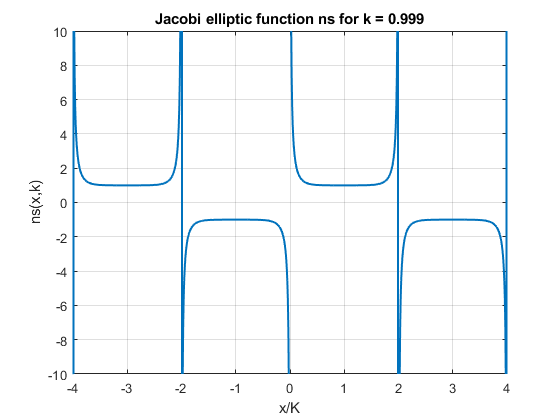

figure
x=-4:0.01:4;
k = 0.999;
K = elK(k);
plot(x,JacobiNS(x*K,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('ns(x,k)')
ylim([-10 10])
title(sprintf('Jacobi elliptic function ns for k = %g',k))
grid on

**Example 2**

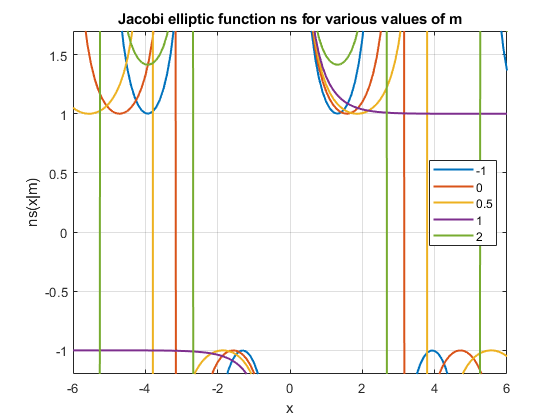

figure
X = -6:0.1:6;
M = [-1,0,0.5,1,2];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiNS(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1.2 1.7])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Jacobi elliptic function ns for various values of m')
xlabel('x')
ylabel('ns(x|m)')

**Example 3**

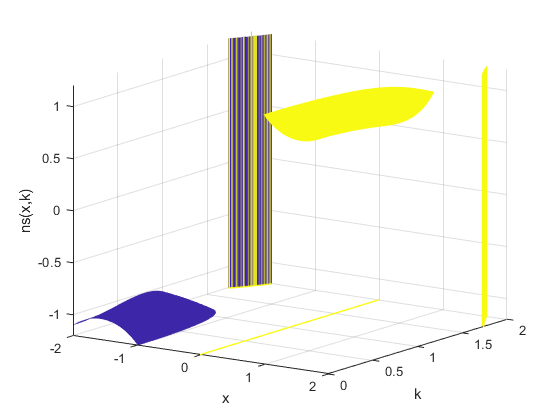

figure
x=-2:0.01:2;
k=0:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiNS(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -1.2;
hc.LineWidth = 1;
hc.LevelList = 0:0.1:1;
caxis([0 1])
view([35 15]);
xlabel('x')
ylabel('k')
zlabel('ns(x,k)')
zlim([-1.2 1.2])
grid on

**Example 4**

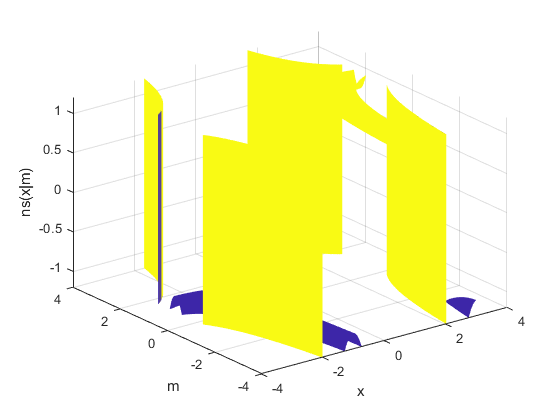

figure
x=-3:0.01:3;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
surface(X,M,mJacobiNS(X,M),'EdgeColor','none')
view(3)
caxis([-1 1])
xlabel('x')
ylabel('m')
zlabel('ns(x|m)')
zlim([-1.2 1.2])
grid on

**Example 5**

[MATLAB example](https://www.mathworks.com/help/symbolic/jacobins.html)

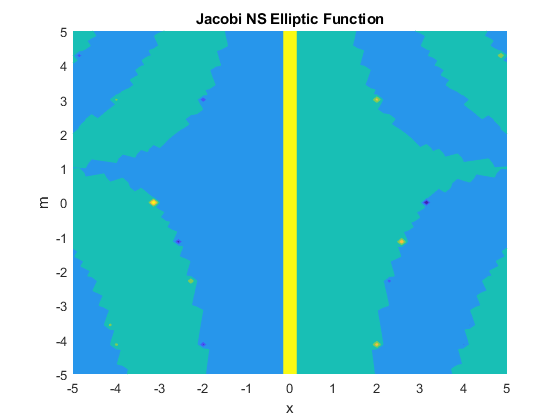

figure
f = @(x,m)mJacobiNS(x,m);
fcontour(f,'Fill','on') %,'LevelList',-3:0.1:3,'MeshDensity',200)
title('Jacobi NS Elliptic Function')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirnsh, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerinshe Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also